% this m-file solves the scalar Riccati differential equation over
% the time interval [t0,T]. The terminal value of the cost is
% assumed equal to zero.

## Part (a-b)

clear P K t


A =  0.5;
B =  1;
Q =  1;
R =  0.1;
t0 = 0;
L = B^2 / R;  % L = l^2

% vector of terminal time, T, values
T=[1,2,3,4,5];

% coefficients of Riccati equation
ARE = [-B/R*B', 2 * A, Q];
Pboth = roots(ARE)

Pboth =     0.3702
   -0.2702


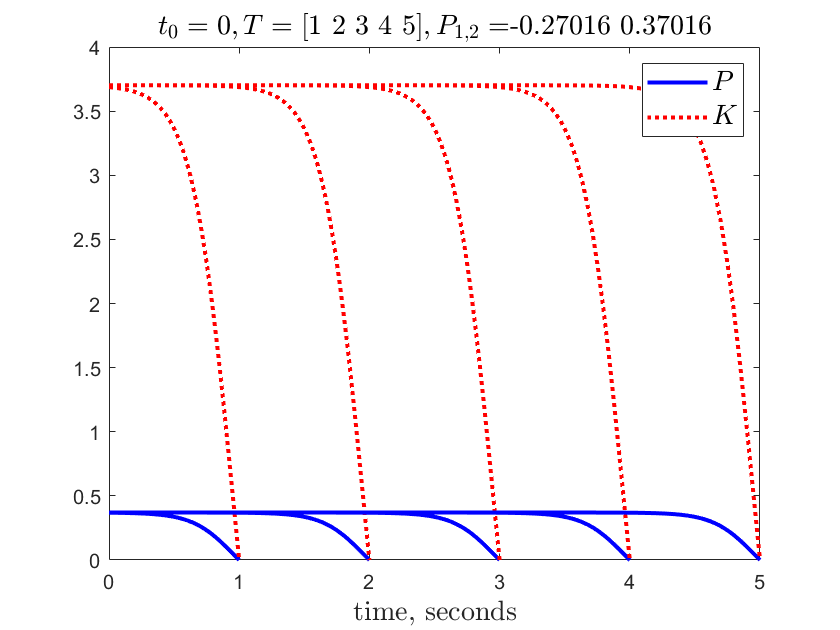

% sort roots of ARE so that P1 < 0, P2 > 0
if Pboth(2) > 0
    P1 = Pboth(1);
	P2 = Pboth(2);
else
    P1 = Pboth(2);
	P2 = Pboth(1);
end


figure(1)
clf

for i = 1:length(T)

    t = linspace(t0,T(i));
    
    % create the optimal cost P(t) as a function of T(i) and the vector t
    num =  P1 * P2 *(exp((P1-P2) * L *(T(i) - t)) -1 );
    den =  - P1 + P2 * exp((P1 - P2) * L * (T(i) - t));
    
    % note use of the ./ operator to do element by element division
    P = num./den;
    K = (B/R)*num./den;
    
    plot(t,P,'b-',t,K,'r:')
    hold on
end
hold off


 h = title(['$$t_0 = 0,  T = [$$',num2str(T),'$$],   P_{1,2} = $$',num2str([P1   P2])]);
 set(h,'interpreter','latex','fontsize',14);
hh = xlabel('time, seconds');
set(hh,'interpreter','latex','fontsize',14);
hhh = legend('$P$','$K$');
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)

As T goes to infinite, the P(t) keeps as constant P2 

limit in (a) is the positive solution of ARE.